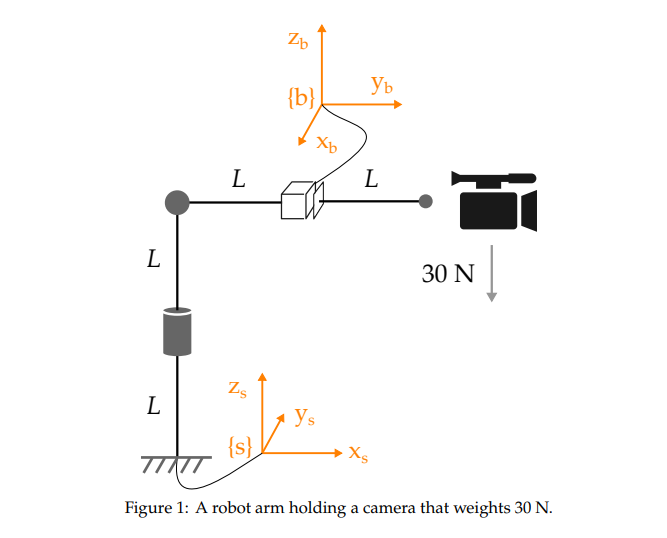

Consider the robot in Figure 1. Find the wrench applied by the camera in frame {𝑠}. 

syms L real

Tsb = [[0 1 0 L]
    [-1 0 0 0]
    [0 0 1 2*L]
    [0 0 0 1]];

adjointTsbinv = adjointM(inv(Tsb))

$$adjointTsbinv = \left(\begin{array}{cccccc} 0 & -1 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 2\,L & 0 & -L & 0 & -1 & 0\\ 0 & 2\,L & 0 & 1 & 0 & 0\\ 0 & -L & 0 & 0 & 0 & 1 \end{array}\right)$$


Adj13 = (adjointM(inv(Tsb)))'*[-30*L;0;0;0;0;-30]

$$Adj13 = \left(\begin{array}{c} 0\\ 60\,L\\ 0\\ 0\\ 0\\ -30 \end{array}\right)$$